clc, clear, close all;

% Clear command window, clear workspace variables, and close all figures

% Load GIFTI toolbox to read GII format (surface-based data)
% Import surface data of Freesurfer template

% Vertices: Locations of individual points (x, y, z) or nodes that make up a surface mesh

% Faces: Polygons formed by connecting the vertices of a surface mesh model
% Faces are defined by indices that specify which vertices are connected to form each face.
% These indices are usually stored in groups of three, representing the three vertices that form a triangular face.

init;

g_mesh = struct with fields:
       faces: [655360×3 int32]
         mat: [4×4 double]
    vertices: [327684×3 single]


g_lh = struct with fields:
       faces: [327680×3 int32]
         mat: [4×4 double]
    vertices: [163842×3 single]


g_rh = struct with fields:
       faces: [327680×3 int32]
         mat: [4×4 double]
    vertices: [163842×3 single]


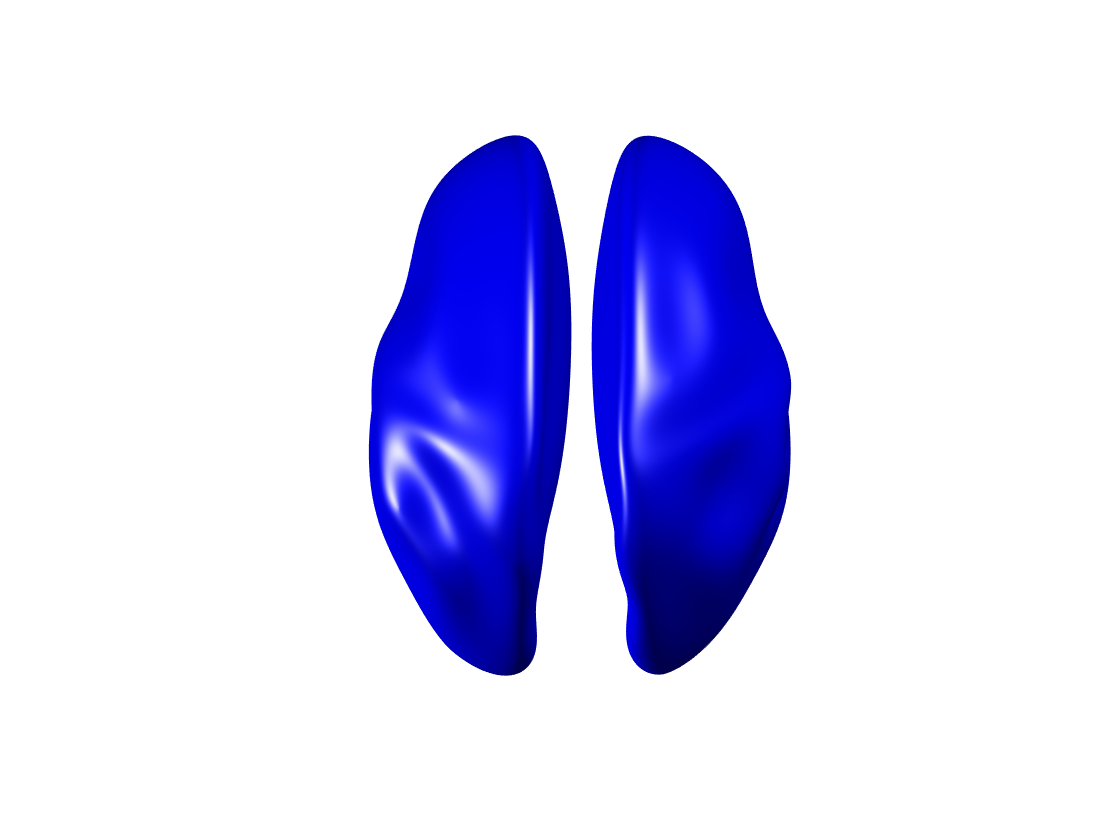


% Initialize the GIFTI toolbox for further operations

% Total vertices are 327,684; each hemisphere of the brain has 163,842 vertices
% (We can use a template with a smaller number of vertices)
n_vertices = size(g_mesh.vertices, 1);

figure;
% Plot brain surface without weight

plot(g_mesh)


% Plot the brain surface without applying any weight

% Plot brain surface with weight from atlas
% Note that the Schaefer atlas is not symmetric, so we have to read annotations for both the left and right hemisphere brain.

% Read annotation: 101 regions in the left brain (100 regions + medial wall of the brain)
[~, gg_lh1_cdata, lh_mapping_table] = read_annotation('brainspace/lh.Schaefer2018_200Parcels_7Networks_order.annot');

% Store the annotation data and mapping table of the left hemisphere

lh_mapping_table

lh_mapping_table = struct with fields:
      numEntries: 101
        orig_tab: 'Schaefer2018_200Parcels_7Networks'
    struct_names: {101×1 cell}
           table: [101×5 double]



% Display the mapping table for the left hemisphere

% Read annotation: 101 regions in the right brain (100 regions + medial wall of the brain)
[~, gg_rh1_cdata, rh_mapping_table] = read_annotation('brainspace/rh.Schaefer2018_200Parcels_7Networks_order.annot');

% Store the annotation data and mapping table of the right hemisphere

rh_mapping_table

rh_mapping_table = struct with fields:
      numEntries: 101
        orig_tab: 'Schaefer2018_200Parcels_7Networks'
    struct_names: {101×1 cell}
           table: [101×5 double]


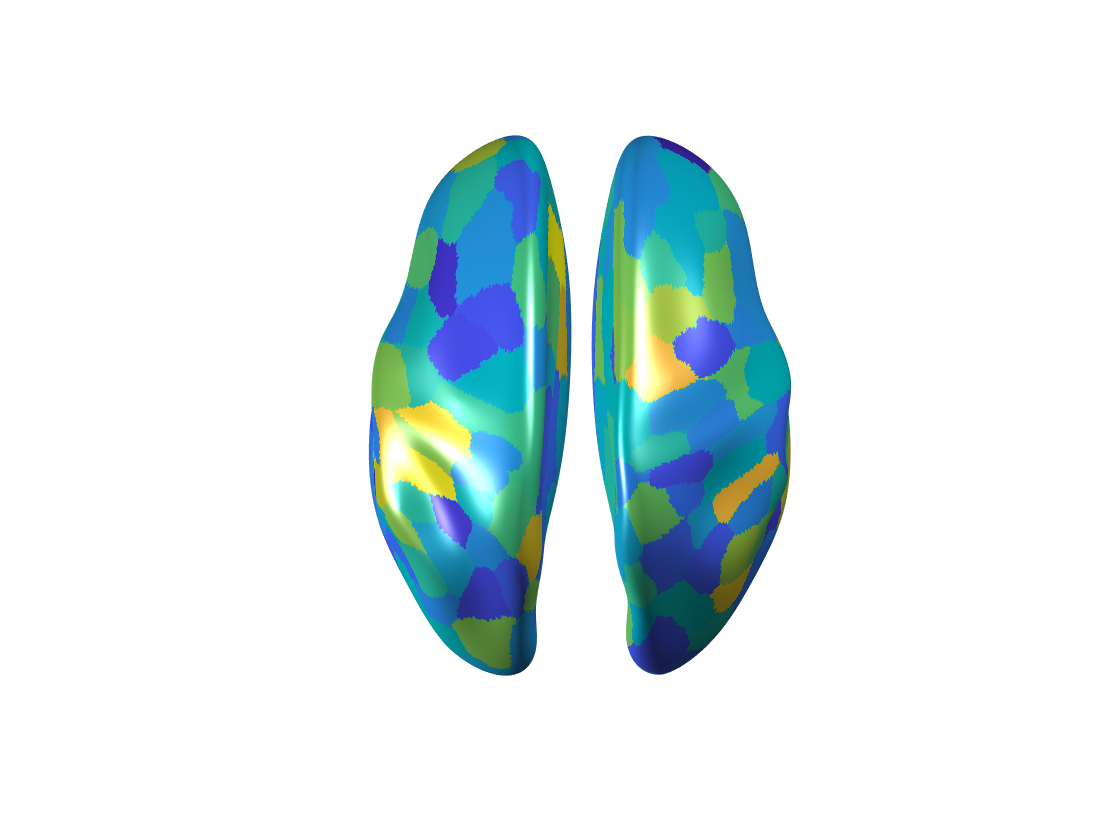


% Display the mapping table for the right hemisphere

% Each region has a specific ID
lh_atlas_id = lh_mapping_table.table(:, 5);
rh_atlas_id = rh_mapping_table.table(:, 5);

% Store the specific ID for each region in the left and right hemisphere

% read weight from csv
table = readtable('data/mean.layer.0.csv');
corticalThicknesses = double(table2array(table(:, 2)));

% Read the cortical thickness data from a CSV file

% Convert weight of 200 regions to weight on the brain surface
w_left_cdata = zeros(n_vertices / 2, 1);
w_right_cdata = zeros(n_vertices / 2, 1);

for j = 1:size(corticalThicknesses, 1) / 2
  % Vlookup mapping table
  w_left_cdata(find(gg_lh1_cdata == lh_atlas_id(j))) = corticalThicknesses(2*j-1);
  w_right_cdata(find(gg_rh1_cdata == rh_atlas_id(j))) = corticalThicknesses(2*j);
end

% Convert the weight of 200 regions to weight on the brain surface
% by mapping the cortical thickness values to the corresponding vertices

final_cdata = [w_left_cdata; w_right_cdata];
gg_mesh.cdata = final_cdata;

% Assign the final weight data to the GIFTI mesh

figure;
plot(g_mesh, gg_mesh)


% Plot the brain surface with the weight data

% Convert MATLAB Live Script to PDF
matlab.internal.liveeditor.openAndConvert('tutorial_livescript.mlx', 'tutorial.pdf', 'HideCode', true);
